# Task 3: Localization under sparse sensor attacks

%-----------------------------------------------------
%  Project "Modeling and Control of CPS"
%           TASK 3 - Localization under sparse attacks
%                               
%                         Latest Update: 21.04.2024
% 
%-----------------------------------------------------
clear
close all
clc

## Data loading

This time  we use real data, in particular we have:

- The dictionary $D\in\mathbb{R}^{100, 25}$ in which we can find the RSS-fingerprinting 

- The vector $y\in\mathbb{R}^{25}$ of the measuremtents

%load the provided data D, y
load localization.mat   

## Hyperparameter setting

%   hyperparameters
p=100;                                   %number of cells of the grid
q=25;                                    %number of sensors
count=0;

delta=1e-15;                             %used in the stop condition                           
                             
tol=0.1;                                 %are really non-zero components?

lambda1=10;   lambda2=20;               %weights of the lasso
eps=1e-8; 
lambda=[lambda1*ones(p,1); lambda2*ones(q,1)];  %sparse
G=[D eye(q)];                                   %augmented sensing matrix
G=normalize(G);
tau= (norm(G)^(-2))-eps;                        %step size

z_calc=zeros((p+q), 1);   %z_0                      
%----------------------------------------------------------

## ISTA implementation for localization purposes

%-------------ISTA for localization------------------------
while 1
    z_prev=z_calc;
    %.........passo k+1 dell'algoritmo
    qi=z_prev+tau*G'*(y-G*z_prev);
    %For each component, apply the S.T. operator
    for j=1:1:(p+q)
        %nuovo elemento di x  
        z_calc(j,1) = sto(qi(j), lambda(j)*tau);
    end
    %......................................................
    if(norm(z_calc-z_prev)<delta)
        break
    end
    count=count+1;
end 

## Data cleaning

tol=4;
for i=1:(p+q)
    if(abs(z_calc(i))<tol)    
        z_calc(i)=0;
    end
end

%Separate x and a
x_calc = z_calc(1:p);
a_calc = z_calc(p+1:end);
Supp_x = find(x_calc)';
Supp_a = find(a_calc)';

## ISTA: Graphical representation of the room

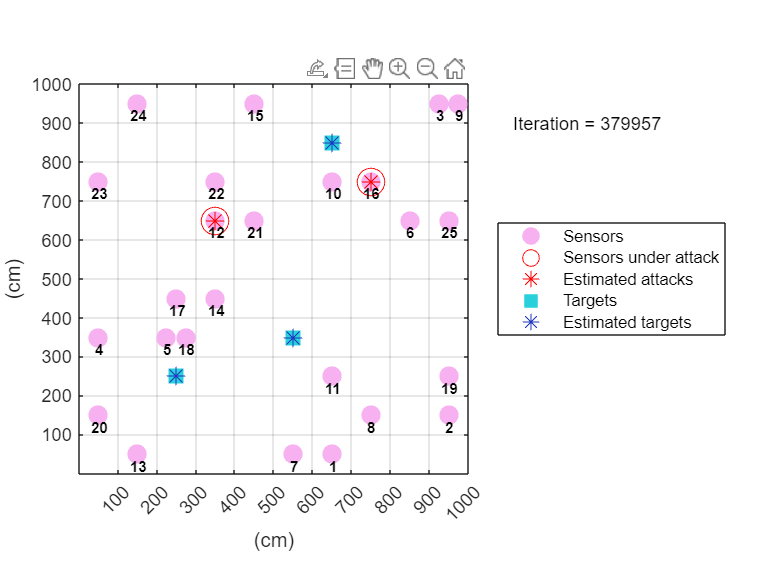

room(Supp_x,Supp_a,"ISTA",count)

count=0;

## Alternative technique to Localization (attack free): K-Nearest Neighbours

%% Alternative to Localization: k-NN (attack free) 
min = 10000;

for d1=1:p
    for d2=1:p
        if d2>=d1
            break
        end
        for d3=1:p
            if d3>=d2
                break
            end            
            %if d2>d1 && d3>d2

            diff = norm(D(:,d1)+D(:, d2)+D(:,d3)-y)^2;
    
            if diff < min
                x1 = d1;
                x2 = d2;
                x3 = d3;
                min = diff;
            end
            count=count+1;    
            %end
        end
    end
end
supp_x_knn(1) = x1;
supp_x_knn(2) = x2;
supp_x_knn(3) = x3;

## K-NN: graphical representation of the room 

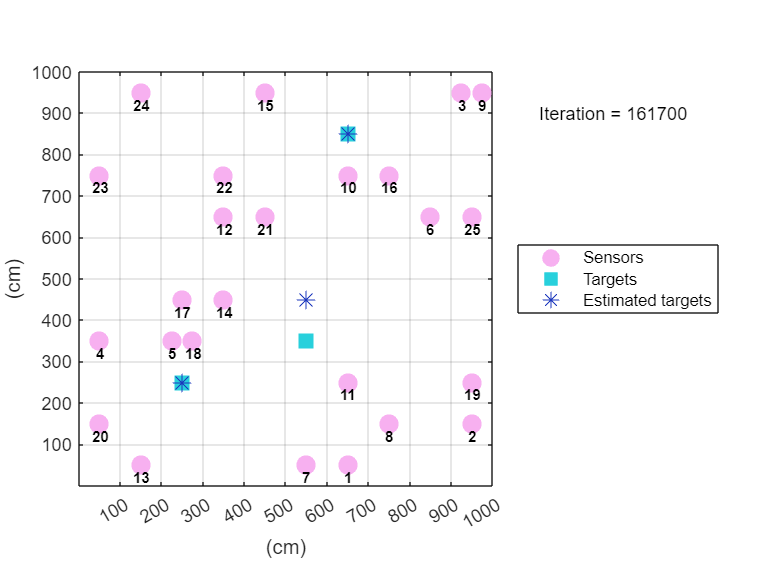

room(supp_x_knn,0,"K-NN",count)